# **기름 값, 오를땐 LTE 내릴땐 거북이... 범인은 누구?**

**데이터분석을 통해 원유가격의 하락에도 잘 떨어지지 않는 휘발유 값의 범인을 알아보자.**

비교 데이터 : 

- 2009 - 2018 기간동안의 원유 값(두바이)

- 싱가폴 정제 마진

- 정유사 공급가(보통 휘발유)

- 유류세

## **원유와 정유사 공급가의 관계**

- 원유가의 변동에 따른 소비자 가격은 비례한가 ?

plot(dateArray,[oil,supply]);
xlabel('날짜(2009 - 2018)');
ylabel('가격(원)');
title('2009 - 2018 원유, 정유사 공급가','fontsize',15);
legend(' 원유 가격',' 정유사 공급가');
ylim([0,2000]);

**⊙ 두 그래프를 통해 유사하게 변화하는 그래프를 볼 수 있지만, 원유가와 정유사 공급가차이의 이유를 설명할 수 없다.**

→ 정유사의 예상 마진(싱가폴정재마진)을 이용해 비교해보자.

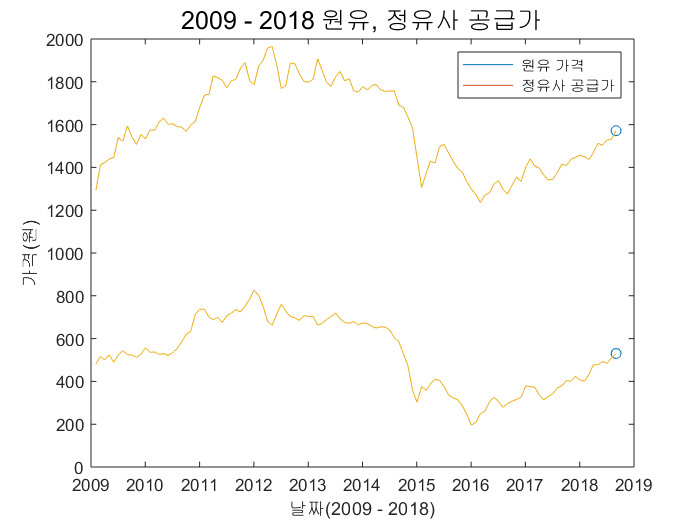

% comet 을 사용한 그래프
hold on
comet(dateArray,oil);
comet(dateArray,supply);
xlabel('날짜(2009 - 2018)');
ylabel('가격(원)');
title('2009 - 2018 원유, 정유사 공급가','fontsize',15);
legend(' 원유 가격',' 정유사 공급가');
ylim([0,2000]);
hold off;

## **정유사의 예상공급가와 실제 공급가**

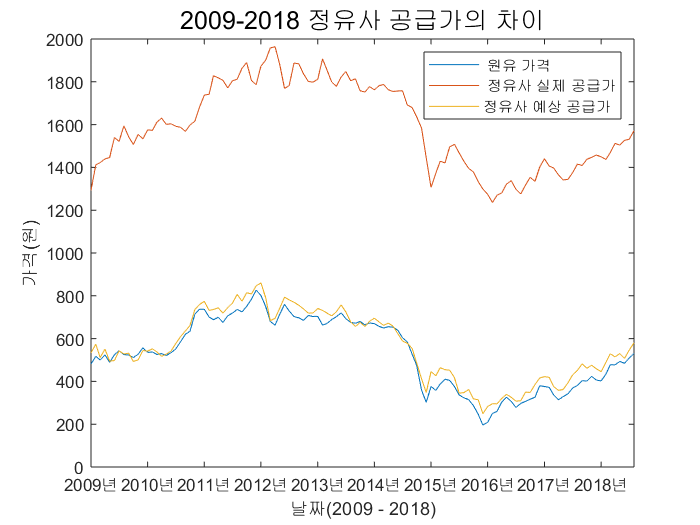

plot(date,[oil,supply,oil_Singapore]);
xlabel('날짜(2009 - 2018)');
ylabel('가격(원)');
title('2009-2018 정유사 공급가의 차이','fontsize',15);
legend(' 원유 가격',' 정유사 실제 공급가','정유사 예상 공급가');

                                                                    **(정유사 예상 공급가 = 원유 가격 + 정유사 예상 마진)**

 싱가폴정재마진을 통해서 정유사의 예상 마진을 구해봤지만 정유사의 예상 공급가와 실제 공급가 사이에는 여전히 큰 차이가 있다.

## **세금이 원인일까?**

- 세금을 제하고 비교해 보았을 때, 우리는 정유소 예상공급가와 세전실제공급가의 차이가 크지 않다는 것에 주목했다.

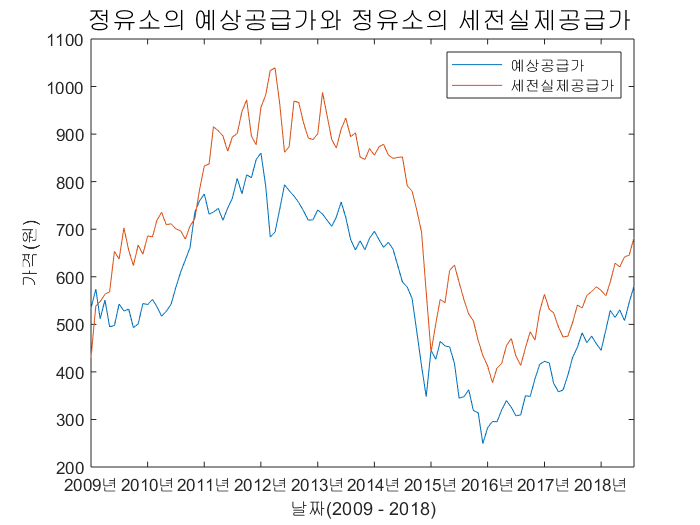

plot(date,[oil+Singapore supply-tax]);
xlabel('날짜(2009 - 2018)');
ylabel('가격(원)');
title('정유소의 예상공급가와 정유소의 세전실제공급가 ','fontsize',15);
legend(' 예상공급가',' 세전실제공급가');

**예상가와 세전 공급가의 차이는 있지만 그 폭이 작고 비례하는 모습을 보인다. 따라서 정유사가 문제의 원인이라고 볼 수 없다.**

## **원유와 유류세**

bar(date,subtax,'stacked');

'subtax'은(는) 정의되지 않은 함수 또는 변수입니다.

title(' 공급가에서 유류세가 차지하는 비중 ','fontsize',15);
xlabel(' 날짜 ( 2009 - 2018 ) ');
ylabel('가격 (원)');
legend(' 유류세의 비중',' 공급가');

**위 그래프를 통해 공급가에서 유류세가 높은 비중을 차지함을 알 수 있다.**

plot(date,[tax,oil]);
xlabel(' 날짜 ( 2009 - 2018 ) ');
ylabel('가격 (원)');
title('원유와 유류세의 관계','fontsize',15);
L = legend(' 유류세',' 원유 값');
set(L,'Location','best');

**원유 값의 큰 변동에도 불구하고 유류세는 큰 변화가 없는 모습이다.**

**즉, 원유 값이 떨어져도 주유소 휘발유 값이 이보다 천천히 떨어지는 이유는 탄력적이지 못한 유류세가 휘발유 가격에 큰 비중을 차지하고 있던 것이 원인이었다.**

## **결론**

[maxoil,maxindex] = max(oil,[],1);
[minoil,minindex] = min(oil,[],1);
a = (maxoil-minoil)/maxoil*100;
maxtax = tax(maxindex);
mintax = tax(minindex);
b = (maxtax-mintax)/maxtax*100;
maxsupply = supply(maxindex);
minsupply = supply(minindex);
c = (maxsupply-minsupply)/maxsupply*100;
his = [a,b,c];

figure
h1 = axes;
name = categorical({'원유', '유류세','정유사 공급가'});
h1bar = bar(name,his);
set(h1, 'Ydir', 'reverse');
set(h1, 'XAxisLocation', 'Top');
h1bar.FaceColor = 'flat';
h1bar.CData(1,:) = [.5 0 0];
h1bar.CData(2,:) = [0 .5 0];
h1bar.CData(3,:) = [0 0 .5];
title('원유, 유류세, 공급가의 감소폭','fontsize',15);
ylim([0,100]);

**원유가 큰 폭으로 감소해도 유류세의 감소폭이 현저하게 작으며 정유사 공급가에 차지하는 비중이 원유보다 크기 때문에 실질적으로 휘발유 값이 많이 내려가지 않았던 것이다!**

# **정유사가 범인인줄 알았지만 정부가 범인이었다...**